% Define the step amplitude vector
simOut_2_1_4 = sim('Lab_1\Point_2_1\2_1_4\Black_box_system_2_1_4.slx');

### Searching for referenced models in model 'Black_box_system_2_1_4'.
### Found 0 model reference targets to update.


Found algebraic loop that contains: 
Black_box_system_2_1_4/Subsystem2/Subsystem/Sum2
Black_box_system_2_1_4/Subsystem2/Subsystem/Sum3
Black_box_system_2_1_4/Subsystem2/Subsystem/Sum4
Black_box_system_2_1_4/Subsystem2/Subsystem/Saturation  (discontinuity)
Black_box_system_2_1_4/Subsystem2/Quanser SRV-02 + NI DAQ1/DAC/Zero-Order Hold


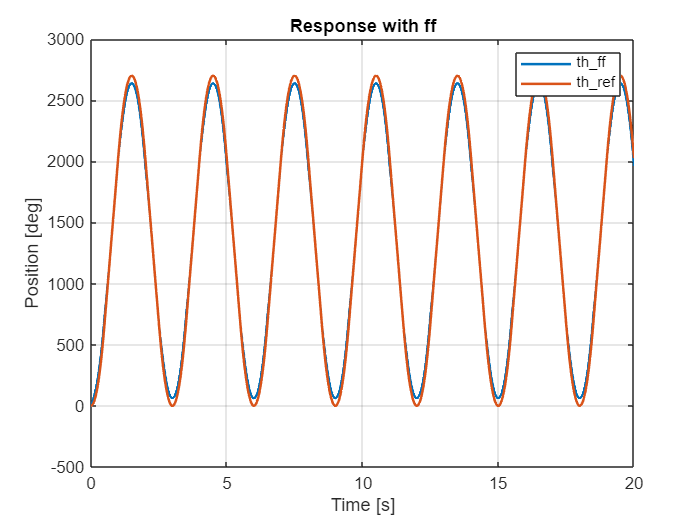


% Create plots
figure; 
plot(simOut_2_1_4.th_ff.time,simOut_2_1_4.th_ff.signals.values, 'LineWidth', 1.5);
grid on;
hold on;

plot(simOut_2_1_4.th_ref.time,simOut_2_1_4.th_ref.signals.values, 'LineWidth', 1.5);

legend('th\_ff', 'th\_ref');
title(sprintf('Response with ff'));
xlabel('Time [s]');
ylabel('Position [deg]')

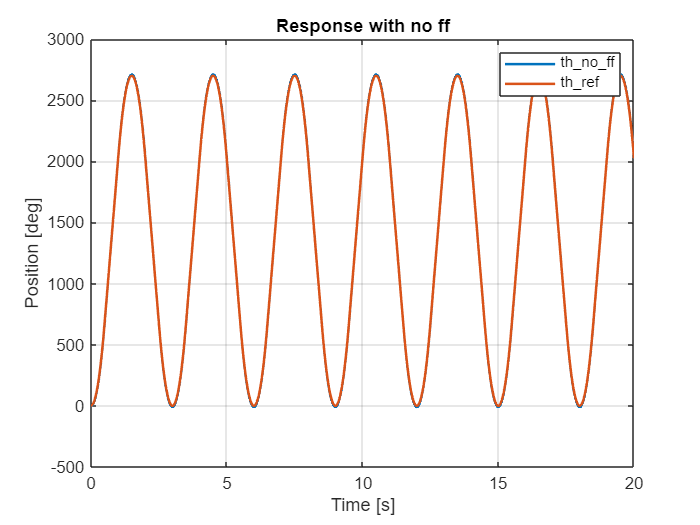

% Create plots
figure; 
plot(simOut_2_1_4.th_no_ff.time,simOut_2_1_4.th_no_ff.signals.values, 'LineWidth', 1.5);
grid on;
hold on;

plot(simOut_2_1_4.th_ref.time,simOut_2_1_4.th_ref.signals.values, 'LineWidth', 1.5);

legend('th\_no\_ff', 'th\_ref');
title(sprintf('Response with no ff'));
xlabel('Time [s]');
ylabel('Position [deg]')